% =========================================================
% malha_aberta.m
% Grupo G1 - Controle de Altitude de Drone
% UTFPR Apucarana - Analise de Sistemas Lineares 2026-1
% =========================================================
% Modelo: m*z'' = T - mg - b*z'
% Linearizando em torno do hover: m*z'' + b*z' = u
% G(s) = Z(s)/U(s) = (1/m) / [s^2 + (b/m)*s]
%        = (1/m) / [s*(s + b/m)]
% Parametros nominais: m = 1.2 kg, b = 0.5 N.s/m
% G(s) = 0.8333 / [s*(s + 0.4167)]
% =========================================================

clear; clc; close all;

%% --- Parametros do sistema ---
m = 1.2;        % massa [kg]
b = 0.5;        % coeficiente de amortecimento [N.s/m]

%% --- Funcao de transferencia da planta ---
% G(s) = (1/m) / (s^2 + (b/m)*s)
num = [1/m];
den = [1, b/m, 0];
G = tf(num, den);

fprintf('=== Funcao de Transferencia G(s) ===\n');

=== Funcao de Transferencia G(s) ===


G


G =
 
      0.8333
  --------------
  s^2 + 0.4167 s
 
Continuous-time transfer function.



p = pole(G);
z = zero(G);
fprintf('Polos de G(s):\n');

Polos de G(s):


for i = 1:length(p)
    fprintf('  p%d = %.4f\n', i, p(i));
end

  p1 = 0.0000
  p2 = -0.4167


if isempty(z)
    fprintf('Zeros: nenhum (sistema sem zeros de malha aberta)\n');
end

Zeros: nenhum (sistema sem zeros de malha aberta)



fprintf('\nObservacao: polo em s=0 -> sistema marginalmente estavel em malha aberta.\n');


Observacao: polo em s=0 -> sistema marginalmente estavel em malha aberta.


fprintf('Polo em s=%.4f -> modo de decaimento exponencial.\n', p(find(p~=0)));

Polo em s=-0.4167 -> modo de decaimento exponencial.


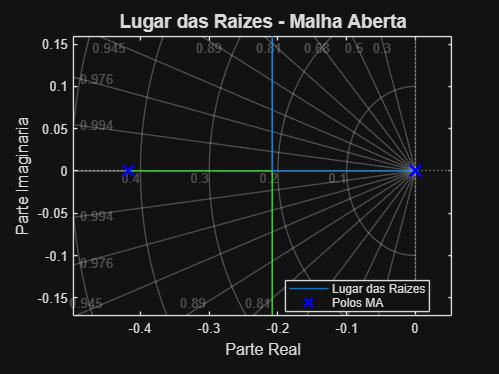


%% --- Figura 1: Lugar das Raizes ---
figure(1);
rlocus(G);
title('Lugar das Raizes - Malha Aberta', 'FontSize', 14);
xlabel('Parte Real', 'FontSize', 12);
ylabel('Parte Imaginaria', 'FontSize', 12);
grid on;
% Marcar polos de malha aberta
hold on;
plot(real(p), imag(p), 'bx', 'MarkerSize', 12, 'LineWidth', 2);
legend('Lugar das Raizes', 'Polos MA', 'Location', 'best');
hold off;

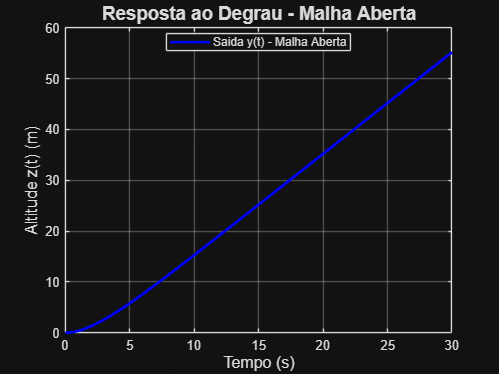


%% --- Figura 2: Resposta ao Degrau em Malha Aberta ---
figure(2);
t_sim = 0:0.01:30;
[y_ma, t_ma] = step(G, t_sim);
plot(t_ma, y_ma, 'b-', 'LineWidth', 2);
title('Resposta ao Degrau - Malha Aberta', 'FontSize', 14);
xlabel('Tempo (s)', 'FontSize', 12);
ylabel('Altitude z(t) (m)', 'FontSize', 12);
grid on;
legend('Saida y(t) - Malha Aberta', 'Location', 'best');

% Nota: resposta diverge (rampa) por causa do polo em s=0
fprintf('\nNota: resposta ao degrau em malha aberta e uma rampa (integracao pura)\n');


Nota: resposta ao degrau em malha aberta e uma rampa (integracao pura)


fprintf('       pois o polo em s=0 introduz um integrador na planta.\n');

       pois o polo em s=0 introduz um integrador na planta.


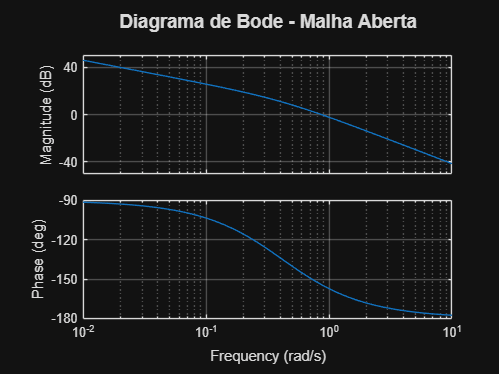


%% --- Figura 3: Diagrama de Bode Completo ---
figure(3);
bode(G);
title('Diagrama de Bode - Malha Aberta', 'FontSize', 14);
grid on;


% Margem de fase e margem de ganho
[Gm, Pm, Wcg, Wcp] = margin(G);
fprintf('\n=== Analise de Estabilidade - Bode ===\n');


=== Analise de Estabilidade - Bode ===


if isinf(Gm)
    fprintf('Margem de Ganho: Infinita (sem cruzamento de fase em -180 graus)\n');
else
    fprintf('Margem de Ganho: %.4f dB (em %.4f rad/s)\n', 20*log10(Gm), Wcg);
end

Margem de Ganho: Infinita (sem cruzamento de fase em -180 graus)


fprintf('Margem de Fase:  %.4f graus (em %.4f rad/s)\n', Pm, Wcp);

Margem de Fase:  25.6779 graus (em 0.8666 rad/s)


fprintf('Observacao: fase parte de -90 graus (integrador) -> margem de fase reduzida.\n');

Observacao: fase parte de -90 graus (integrador) -> margem de fase reduzida.


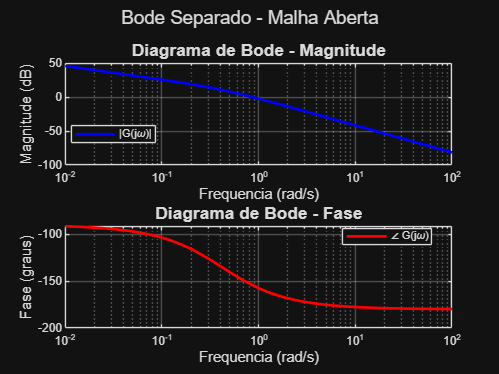


%% --- Figura 4: Bode Separado Magnitude e Fase ---
figure(4);
w = logspace(-2, 2, 500);
[mag, phase, wout] = bode(G, w);
mag_db = 20*log10(squeeze(mag));
phase_deg = squeeze(phase);

subplot(2,1,1);
semilogx(wout, mag_db, 'b-', 'LineWidth', 2);
title('Diagrama de Bode - Magnitude', 'FontSize', 13);
xlabel('Frequencia (rad/s)', 'FontSize', 11);
ylabel('Magnitude (dB)', 'FontSize', 11);
grid on;
legend('|G(j\omega)|', 'Location', 'best');

subplot(2,1,2);
semilogx(wout, phase_deg, 'r-', 'LineWidth', 2);
title('Diagrama de Bode - Fase', 'FontSize', 13);
xlabel('Frequencia (rad/s)', 'FontSize', 11);
ylabel('Fase (graus)', 'FontSize', 11);
grid on;
legend('\angle G(j\omega)', 'Location', 'best');
sgtitle('Bode Separado - Malha Aberta', 'FontSize', 14);


fprintf('\n=== Script malha_aberta.m executado com sucesso ===\n');


=== Script malha_aberta.m executado com sucesso ===


fprintf('Salvar figuras: File > Export Setup > 600 dpi > Export\n');

Salvar figuras: File > Export Setup > 600 dpi > Export


fprintf('  fig1_rlocus.png\n');

  fig1_rlocus.png


fprintf('  fig2_step.png\n');

  fig2_step.png


fprintf('  fig3_bode.png\n');

  fig3_bode.png


fprintf('  fig4_bode_separado.png\n');

  fig4_bode_separado.png
